## **I. Sinais Compostos por Sinusoides**

**1. Determine o período, a frequência e o valor máximo (valor de pico) de cada um dos seguintes sinais periódicos. Verifique visualmente no MATLAB.**

Fa = 1000 % Freq Amostragem

Fa = 1000

Ta = 1/Fa % Periodo Amostragem

Ta = 1.0000e-03

a) 𝑥(𝑡) = 2 sin(4𝜋𝑡)

T = 1/2;
t = 0: Ta : 3 * T - Ta;
x = 2*sin(4*pi*t);
plot(t,x)
title("a)")
grid on


Px = potencia(x,Ta,T)

Px = 2


% Periodo é 1/2
% Frequencia é 2
% Amplitude é 2

b) 𝑦(𝑡) = sin(10𝜋𝑡 + 𝜋/2)

T = 1/5;
t = 0: Ta : 3 * T - Ta;
y = sin(10*pi*t + pi/2);
plot(t,y)
title("b)")
grid on


Py = potencia(y,Ta,T)

Py = 0.5000


% Periodo é 1/5
% Frequencia é 5
% Amplitude é 1


c) 𝑝(𝑡) = sin(20𝜋𝑡 + 70𝜋/180) + sin(20𝜋𝑡 + 200𝜋/180)

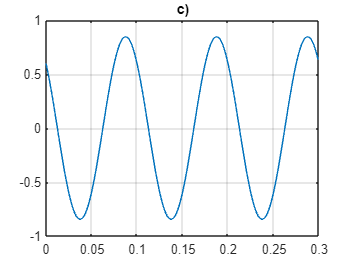

T = 0.1;
t = 0:Ta:3*T-Ta;
p = sin(20*pi*t + 70*pi/180) + sin(20*pi*t + 200*pi/180);
plot(t, p)
title("c)")
grid on


P = potencia(p,Ta,T)

P = 0.3572


% Periodo é 1/10
% Frequencia é 10
% Amplitude é aprox 0.8


d) 𝑧(𝑡) = sin(6𝜋𝑡) + sin(8𝜋𝑡)

%% sin(6*pi*t)
T1 = (2*pi)/(6*pi);
%% sin(8*pi*t)
T2 = (2*pi)/(8*pi);
%% Para calcular o T da função z, é necessário encontrar o LCM
%% entre T1 e T2, neste caso entre 1/3 e 1/4. LCM(1/3,1/4) é 1.
T = 1;
t=0:Ta:3*T-Ta;
z=sin(6*pi*t)+sin(8*pi*t);
plot(t,z)
title("d)")
grid on

Pz = potencia(z,Ta,T)

Pz = 1


% Periodo é 1
% Frequencia é 1
% Amplitude é aprox 2

e) 𝑤(𝑡) = sin(6𝜋𝑡) + sin(8𝜋𝑡 + 0.1)

T = 1;
t = 0:Ta:3*T-Ta;
w = sin(6*pi*t) + sin(8*pi*t + 0.1);
plot(t,w)
title("e)")
grid on

Pw = potencia(w,Ta,T)

Pw = 1.0000


% Periodo é 1
% Frequencia é 1
% Amplitude é aprox 2 - 0.1

f) 𝑞(𝑡) = sin(6𝜋𝑡) + sin(7𝜋𝑡) + sin(8𝜋𝑡)

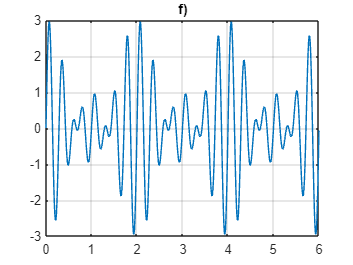

%% sin(6*pi*t)
T1 = (2*pi)/(6*pi);
%% sin(7*pi*t)
T2 = (2*pi)/(7*pi);
%% sin(8*pi*t)
T3 = (2*pi)/(8*pi);
%% Para calcular o T da função z, é necessário encontrar o LCM
%% entre T1, T2 e T3, neste caso entre 1/3, 2/7 e 1/4. 
%% LCM(1/3,2/7,1/4) é 2.
T = 2;
t = 0:Ta:3*T-Ta;
q = sin(6*pi*t) + sin(7*pi*t) + sin(8*pi*t);
plot(t,q)
title("f)")
grid on


Pq = potencia(q,Ta,T)

Pq = 1.5000


% Periodo é 2
% Frequencia é 1/2
% Amplitude é aprox 3

**2. Com base no que verificou na alínea 1, obtenha a relação que determina o período de um sinal genérico descrito por:**

**x(𝑡) =(N n=1) ∑ 𝐴𝑛 sin(2𝜋𝑓𝑛𝑡 + 𝜙𝑛)**

%% O que determina o periodo de um sinal genérico é o minimo
%% múltiplo comum entre os periodos de cada função seno pertencente 
%% à função original.

**3. Determine a potência associada a cada um dos sinais representados na alínea 1. Desenvolva uma função no MATLAB que, aceitando como argumentos de entrada o vetor de amostras de um sinal, 𝑥, o período de amostragem referente a esse sinal, 𝑇𝑎, e o período do sinal, 𝑇, retorna a potência associada ao sinal.**

%% Função no fim do LiveScript.

**4. Considere um conjunto de sinais definidos pela expressão da alínea 2, onde 𝑁 = 3, 𝐴1 = 𝐴2 = 𝐴3 = 1, e 𝑓1 = 10𝐻𝑧, 𝑓2 = 20𝐻𝑧 𝑒 𝑓3 = 30 𝐻𝑧. Testando diferentes valores para 𝜙𝑛, 𝑛 = 1,2,3, determinados aleatoriamente entre ] − 𝜋; 𝜋], mostre que as realizações obtidas para o sinal 𝑥(𝑡) são muito distintas entre si (e que o valor de pico varia notoriamente), mas que todas mantêm a mesma potência. Explique esta observação.**

N = 3;
A = [1 1 1];
f = [10 20 30];
%% Para calcular o T da função x, é necessário encontrar o LCM
%% entre T1, T2 e T3, neste caso entre 1/10, 1/20 e 1/30. 
%% LCM(1/10,1/20,1/30) é 1/10.
T = 1/10

T = 0.1000

t = 0:Ta:3*T-Ta;

x = 0;
%% Gerar um vetor com 3 valores entre -pi e pi:
phi = -pi + (pi - (-pi)).*rand(1,3)

phi =    -0.4030   -0.3344   -1.2167


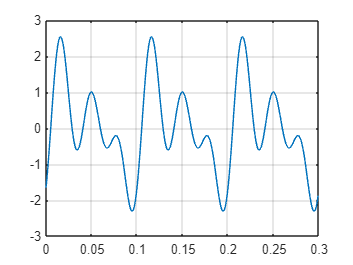



for i = 1:N
    x = x + A(i)*sin(2*pi*f(i)*t+phi(i));
end

soma = sum(x);
plot(t, x)
grid on


P = potencia(x,Ta,T)

P = 1.5000

Função Potencia:

function P = potencia(x,Ta,T)
    Tmax = T/Ta;
    x = x(:,1:Tmax);
    P = x*x'/Tmax;
end